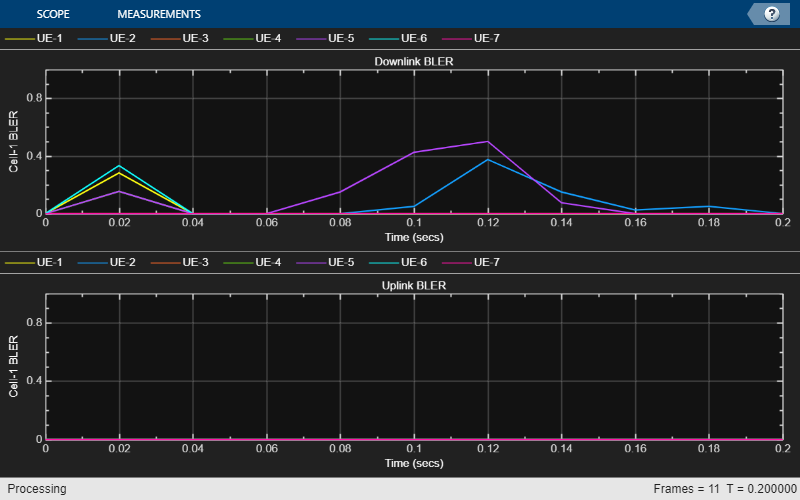

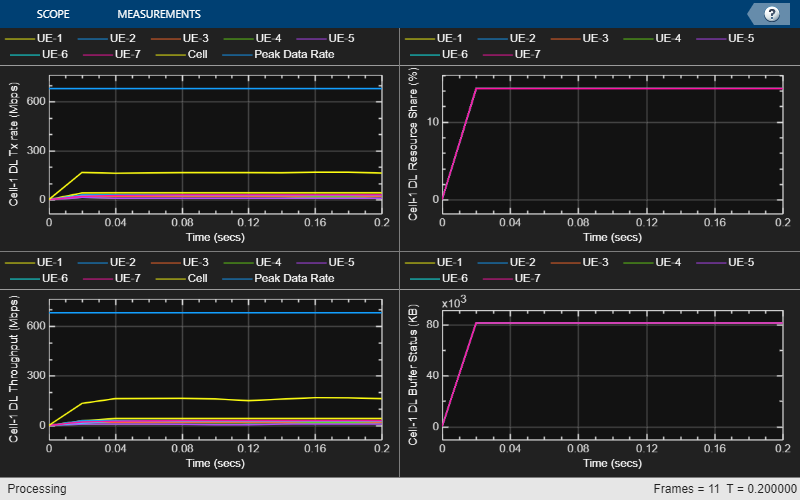

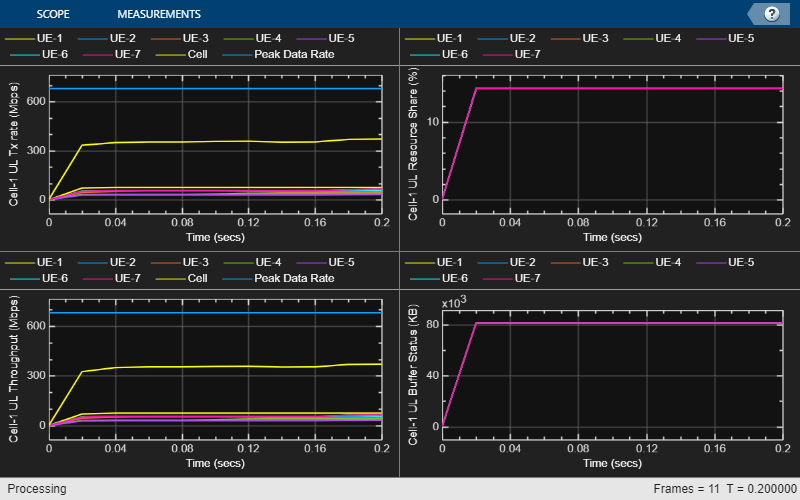

wirelessnetworkSupportPackageCheck

rng("default") % Reset the random number generator
numFrameSimulation = 20; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

phyAbstractionType = "none";

% Urban Scenario
gNB = nrGNB(Name="gNB", CarrierFrequency=3.5e9, ChannelBandwidth=100e6, SubcarrierSpacing=30e3, PHYAbstractionMethod= phyAbstractionType, ReceiveGain=15,TransmitPower=30);

uePositions = [1000 0 0; 2000 0 0; 3000 0 0; 4000 0 0; 3500 0 0; 2500 0 0; 1500 0 0];
ueNames = "UE-" + (1:size(uePositions,1));
UEs= nrUE(Name=ueNames, Position=uePositions, TransmitPower=23,PHYAbstractionMethod=phyAbstractionType);

connectUE(gNB,UEs,FullBufferTraffic="on");

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

channelConfig = struct("DelayProfile","CDL-C","DelaySpread",300e-9);
channels = createCDLChannels(channelConfig,gNB,UEs);
exist("createCDLChannels");

customChannelModel = hNRCustomChannelModel(channels,struct(PHYAbstractionMethod=phyAbstractionType));
addChannelModel(networkSimulator,@customChannelModel.applyChannelModel)

if strcmp(phyAbstractionType, "none") % IQ sample capture only applies to full-PHY
    enableIQSampleCapture = false;
    if enableIQSampleCapture
        iqSampleObj = helperCaptureIQSamples.empty;
        % Set up IQ sample capture on gNB
        iqSampleObj(1) = helperCaptureIQSamples(gNB,Bandwidth=gNB.ChannelBandwidth);
        % Set up IQ sample capture on the UEs
        enableIQSampleCaptureUE = false;
        if enableIQSampleCaptureUE
            for idx = 1:numel(UEs)
                iqSampleObj(1+idx) = helperCaptureIQSamples(UEs(idx),Bandwidth=gNB.ChannelBandwidth);
            end
        end
    end
end

enableTraces = true;

if enableTraces
    % Create an object for scheduler traces logging
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object for PHY traces logging
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UEs);
end

numMetricsSteps = 10;

metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,NumMetricsSteps=numMetricsSteps,...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true);

simulationLogFile = "simulationLogs"; % For logging the simulation traces

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation * 1e-2;
% Run the simulation
run(networkSimulator,simulationTime);


gNBStats = statistics(gNB);
ueStats = statistics(UEs);

displayPerformanceIndicators(metricsVisualizer)

Peak UL Throughput: 679.36 Mbps. Achieved Cell UL Throughput: 354.03 Mbps
Achieved UL Throughput for each UE: [74.09        54.17        49.45        35.99        29.26        55.13        55.95]
Peak UL spectral efficiency: 6.79 bits/s/Hz. Achieved UL spectral efficiency for cell: 3.54 bits/s/Hz 
Block error rate for each UE in the uplink direction: [0  0  0  0  0  0  0]

Peak DL Throughput: 679.36 Mbps. Achieved Cell DL Throughput: 158.87 Mbps
Achieved DL Throughput for each UE: [40.64        25.96        20.51        10.89         8.36        24.66        27.85]
Peak DL spectral efficiency: 6.79 bits/s/Hz. Achieved DL spectral efficiency for cell: 1.59 bits/s/Hz
Block error rate for each UE in the downlink direction: [0.028       0.065           0       0.015        0.13       0.033           0]




if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct("DLTimeStepLogs",[],"ULTimeStepLogs",[],...
            "SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct("TimeStepLogs",[],"SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Get the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Get the Phy reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

if enableIQSampleCapture && strcmp(phyAbstractionType, "none")
  signalAnalyzer(iqSampleObj(1).IQSamples);
end

function channels = createCDLChannels(channelConfig,gNB,UEs)
    %createCDLChannels Create channels between gNB node and UE nodes in a cell
    %   CHANNELS = createCDLChannels(CHANNELCONFIG,GNB,UES) creates channels
    %   between GNB and UES in a cell.
    %
    %   CHANNELS is a N-by-N array where N is the number of nodes in the cell.
    %
    %   CHANNLECONFIG is a struct with these fields - DelayProfile and
    %   DelaySpread.
    %
    %   GNB is an nrGNB node.
    %
    %   UES is an array of nrUE nodes.
    
    numUEs = length(UEs);
    numNodes = length(gNB) + numUEs;
    % Create channel matrix to hold the channel objects
    channels = cell(numNodes,numNodes);
    
    % Get the sample rate of waveform
    waveformInfo = nrOFDMInfo(gNB.NumResourceBlocks,gNB.SubcarrierSpacing/1e3);
    sampleRate = waveformInfo.SampleRate;
    channelFiltering = strcmp(gNB.PHYAbstractionMethod,'none');

    for ueIdx = 1:numUEs
        % Configure the UL channel model between gNB and UE
        channel = nrCDLChannel;
        channel.DelayProfile = channelConfig.DelayProfile;
        channel.DelaySpread = channelConfig.DelaySpread;
        channel.Seed = 73 + (ueIdx - 1);
        channel.CarrierFrequency = gNB.CarrierFrequency;
        channel = hArrayGeometry(channel,UEs(ueIdx).NumTransmitAntennas,gNB.NumReceiveAntennas,...
            'uplink');
        channel.SampleRate = sampleRate;
        channel.ChannelFiltering = channelFiltering;
        channels{UEs(ueIdx).ID, gNB.ID} = channel;
    
        % Configure the DL channel model between gNB and UE
        channel = nrCDLChannel;
        channel.DelayProfile = channelConfig.DelayProfile;
        channel.DelaySpread = channelConfig.DelaySpread;
        channel.Seed = 73 + (ueIdx - 1);
        channel.CarrierFrequency = gNB.CarrierFrequency;
        channel = hArrayGeometry(channel,gNB.NumTransmitAntennas,UEs(ueIdx).NumReceiveAntennas,...
            'downlink');
        channel.SampleRate = sampleRate;
        channel.ChannelFiltering = channelFiltering;
        channels{gNB.ID, UEs(ueIdx).ID} = channel;
    end
end